# Résolution de l'équation de TD I.4. par la méthode de tir


$$1+f'''+f \,f" -f'f'=0$$


avec $f(0)=0$, $f'(0)=0$ et $f'(inf)=1$

clc
clear all
close all

## **Résolution numérique**

**Définition du système à résoudre : ****voir à la fin**

**Paramètre de tir** $s=f''(0)$ à faire varier pour vérifier $f'(\infty) = 1$

s=1.225;    

Solution initiale

y0=zeros(6,1);
y0(1) = 0;
y0(2) = 0;
y0(3) = s;
y0(4) = 0;
y0(5) = 0;
y0(6) = 1;

Paramètres de résolution numérique

options = odeset('RelTol',1e-6, 'AbsTol',1e-5);
eta_in  = 0:0.0001:20; % Valeurs de eta pour lesquelles on souhaite une valeur
epsilon_s=0.00001;
epsilon_result=0.0001;
objective=1;

**Résolution Numérique** par Runge-Kutta et méthode de Newtown

[eta,Y]  = ode45(@td_system,eta_in,y0);
f        = Y(:,1);
f_prime  = Y(:,2);
f_second = Y(:,3);
f_prime_end = f_prime(end);
U=Y(end,5);
s0=0;
s1=s;
while and(abs(s1-s0)>epsilon_s,abs(f_prime_end-objective)>epsilon_result) 
    s0=s1;
    s1=s1-(f_prime_end-objective)/U;
    y0(3)=s1;
    [eta,Y]  = ode45(@td_system,eta_in,y0);
    f        = Y(:,1);
    f_prime  = Y(:,2);
    f_second = Y(:,3);
    f_prime_end = f_prime(end);
    U=Y(end,5);
end
s=s1

s = 1.2326

Tracé de la solution

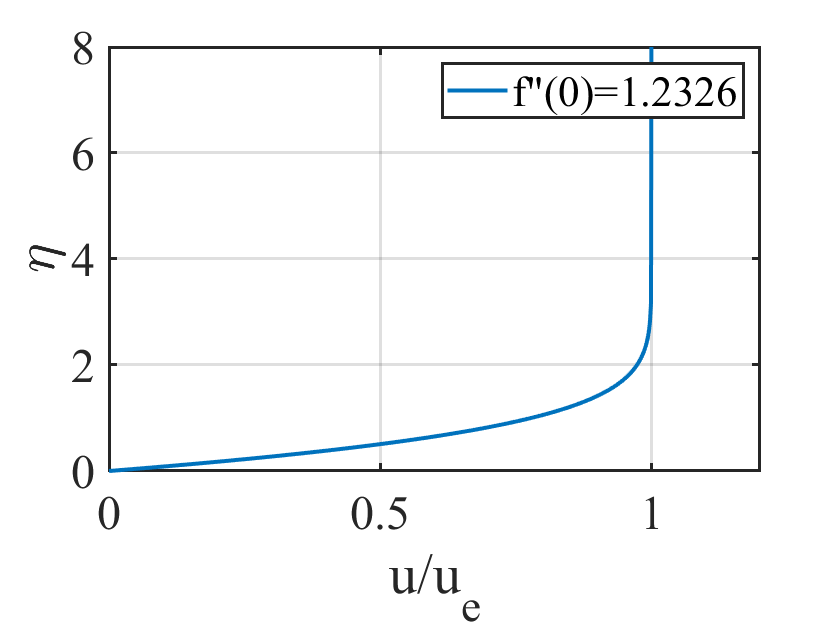

figure(1)
plot(f_prime,eta)
txt=['f"(0)=',num2str(s)];
legend(txt)
set(gca,'fontsize',24,'fontname','times','linewidth',1.5)
ylabel('\eta','fontname','times','fontsize',28)
xlabel('u/u_e','fontname','times','fontsize',28)
set(get(gca,'children'),'linewidth',2)
grid on
xlim([0 1.2])
ylim([0 8])

## Calcul des grandeurs caractéristiques de couche limite

- Calcul du coefficient d'épaisseur de couche limite $\delta_{99}/\delta$ par interpolation du profil $f'(\eta)$

eta_99 = interp1(f_prime, eta, 0.99, 'spline')

eta_99 = 2.3799

- Calcul du coeff. d'épaisseur de déplacement $\delta^*/\delta$

coeff_delta_star = trapz(eta,1-f_prime) 

coeff_delta_star = 0.6479

 La fonction trapz permet de calculer une intégrale par la méthode des trapèzes.

- Calcul du coeff. d'épaisseur de quantité de mouvement $\theta/\delta$

coeff_theta = trapz(eta,f_prime.*(1-f_prime)) 

coeff_theta = 0.2923

- Coefficient de frottement $\frac{c_f }{\left(\frac{\delta }{x}\right)}$

cf=2*f_second(1)

cf = 2.4651

##  Reconstruction du champ de vitesse $u(x,y)$

 Vitesse externe

Ve = 1.0;

Viscosité cinétique

nu = 1.0e-4;

densité

rho=10^(-3);

 Domaine

Lx=0.01;
Ly=0.01;

Calcul de paramètre intermédiaire

a=Ve/Ly;
delta=sqrt(nu/a);

Champs dans la Couche limite

[x,y] = meshgrid(-Lx:Lx*0.05:Lx,0:Ly*0.05:Ly);
my_eta=y/delta;
v=-a.*delta.*interp1(eta,f,my_eta);
u=a.*x.*interp1(eta,f_prime,my_eta);
phi=a.*x.*delta.*interp1(eta,f,my_eta);% ligne de courant

 Figure

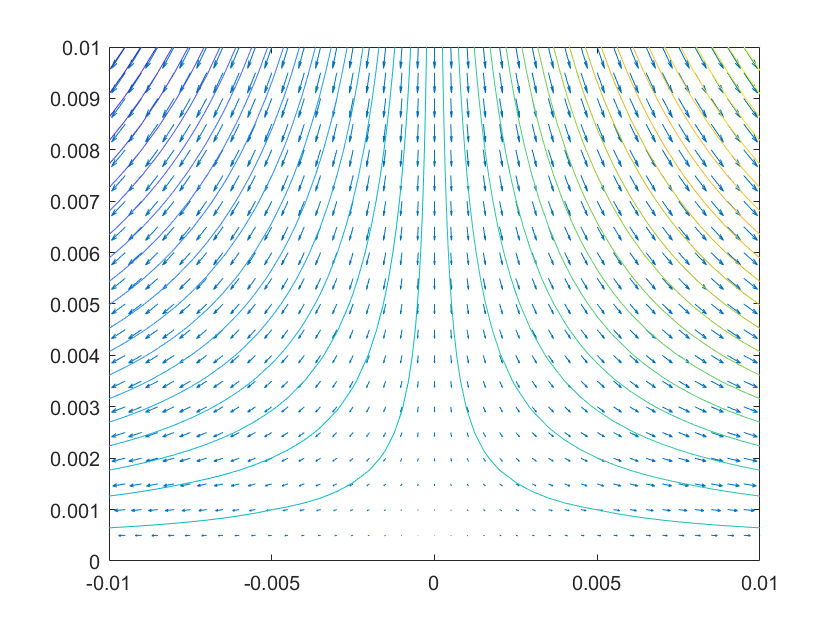

figure(2);
quiver(x,y,u,v)
hold on;
contour(x,y,phi,40)
xlim([-Lx Lx])
ylim([0 Ly])

## **Définition du système à résoudre**

function dy = td_system(~,y)
dy = zeros(6,1);
dy(1) = y(2);
dy(2) = y(3);
dy(3) = y(2)*y(2)-y(1)*y(3)-1; 
dy(4) = y(5);
dy(5) = y(6);
dy(6) = 2*y(2)*y(5)-y(1)*y(6)-y(4)*y(3);
end